%改变MLA pitch，进而改变其FN，探究FN和u，sigma的关系
%改变beamSize，四组B值，不改变FL


clear;
close all;

## 添加路径

addpath('plane wave\')
addpath('镜头\')

## 参数设置

# Gaussian Beam

lambda=647e-6;

beamAmp=1;
noise=0.3;

color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, 'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)

# MLA

rate=(0.15/40);%采样率（global）
rla1=-1.1;% 透镜1的曲率半径  
BB=[1,3,6,10]*2;
N=11:2:81;%微透镜单元采样点数
d = N*rate;% 透镜单元边长
beamSize=BB'*d;
%beamSize=5;
beamStd=beamSize/2.85;
num=max(max(beamStd))./d*5;%数量
area1 = mean(num.*d);%光场的面积
n=round(area1/rate);
t = 1.2;%透镜厚度
material={"F_SILICA"};
area2=12.9;
area3=12.8;

area2=findClosestDivisible(area2,rate);


distance1 = 0.761;   % 投影距离
distance2 = 70;   % 投影距离
distance3 = 74.9;

# Fourier Lens

Dfl = area2;              %采样区域
file='OLD2440-T2M(JCOPTIX-F=74.9胶合).txt';
FL=readLens(file,lambda);

# Diffuser

rpm=50000;%电机转速(圈每分钟)
rpus=rpm/60/1000/1000;
radius_diffuser=22;%散射片半径mm
velocity=2*pi*rpus*radius_diffuser;%线速度
deltat=n*0.033*rate/velocity;%
T=100;%积分时间（μs）
times=floor(T/deltat);
route=velocity*T;
if route>2*pi*radius_diffuser
    route=2*pi*radius_diffuser;
    T=route/velocity;
    times=floor(T/deltat);
end
diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);
phase=Diffuser.generateDiffuser(diffuser,rate,[round(route/rate)+n,n]);

## 生成透镜相位

%% 生成傅里叶透镜厚度函数
Lens.lensThickFcn(FL,Dfl,round(area2/rate));

Lens.lensSingle(FL);

Diffuser.diffuserSingle(diffuser)
rate= single(rate);
lambda= single(lambda);
distance2= single(distance2);
distance3= single(distance3);
area1= single(area1);
area2= single(area2);
area3= single(area3);

if canUseGPU
    Lens.lensGPUArray(FL)
    Diffuser.diffuserGPUArray(diffuser)
    rate= gpuArray(rate);
    lambda= gpuArray(lambda);
    distance2= gpuArray(distance2);
    distance3= gpuArray(distance3);
    area1= gpuArray(area1);
    area2= gpuArray(area2);
    area3= gpuArray(area3);
end

area=[area1,area1,area2,area3];
distance=[20,distance1,distance2,distance3];
u=zeros(length(BB),length(d));
sigma=u;
fn=u;


for kk=1:length(BB)
for jj=1:length(d)
beam=GaussianBeam(beamAmp,beamStd(kk,jj),lambda);
beams=GaussianBeam.defocused(beam,10,n,rate);

MLA1=Lens([rla1,inf],t,d(jj),material,lambda);
MLA2=Lens([inf,-rla1],t,d(jj),material,lambda);
%%生成匀光微透镜阵列厚度函数
Lens.lensArrayThickFcn(MLA1,N(jj),num(jj),'square');
Lens.lensArrayThickFcn(MLA2,N(jj),num(jj),'square');

Lens.lensSingle(MLA1)
Lens.lensSingle(MLA2)
if canUseGPU
    Lens.lensGPUArray(MLA1)
    Lens.lensGPUArray(MLA2)
end

I=zeros(round(area3/rate));

lensgroup={MLA1,MLA2,FL};

## 光场变换

tic
for ii=1:times
    %叠加随机相位
    beamss=GaussianBeam.beamNoise(beams,0.05,0);
    F = transform(beamss, area1, lambda,20, [rate, rate]);
    
    index=round((velocity*(ii-1)*deltat)/rate+1);
    F=F.*phase(index:index+size(F,1)-1,:);
    F=ASMlensgroup(F,lensgroup,distance,area,lambda,rate);

    I_now=abs(F).^2;
    I = I+I_now;

    


    subplot(12,10,[91,100])
    progressBar([100,1000],ii/times)
    drawnow
end

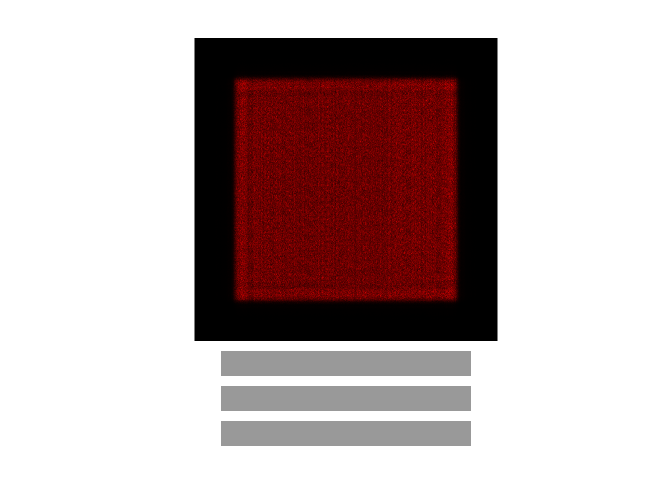


Inorm=imnorm(I);
subplot(12,10,[1,90])
imshow(uint16(Inorm*65536),mymap)
subplot(12,10,101:110)
progressBar([100,1000],jj/length(d))
[u(kk,jj),sigma(kk,jj)]=homoanalyse(Inorm);
fn(kk,jj)=fresnelnum(MLA1,lambda);
end
subplot(12,10,111:120)
progressBar([100,1000],kk/length(BB))
end

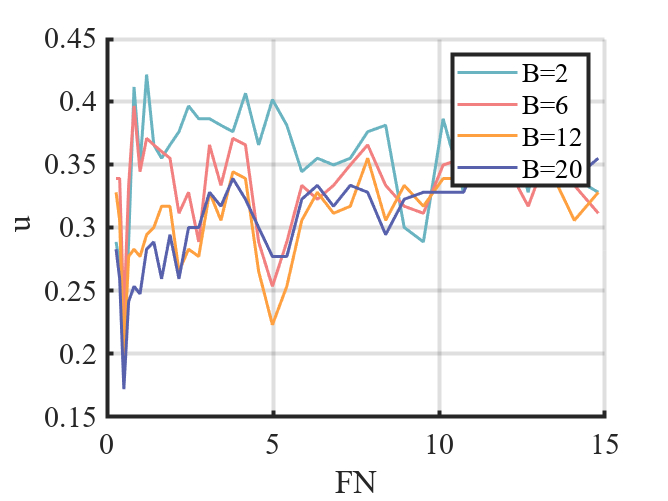

load('E:\File\Matlab\资料\color.mat');

figure
hold on
colororder([color4;color3;color2;color1])
for ii=1:length(BB)
    plot(fn(ii,:),u(ii,:),'LineWidth',1.5)
end
set(gca,'LineWidth',2,'fontname','Times New Roman','Fontsize',15)
xlabel('FN')
ylabel('\it u')
legend(['B=' num2str(BB(1))],['B=' num2str(BB(2))], ...
    ['B=' num2str(BB(3))],['B=' num2str(BB(4))])
grid on

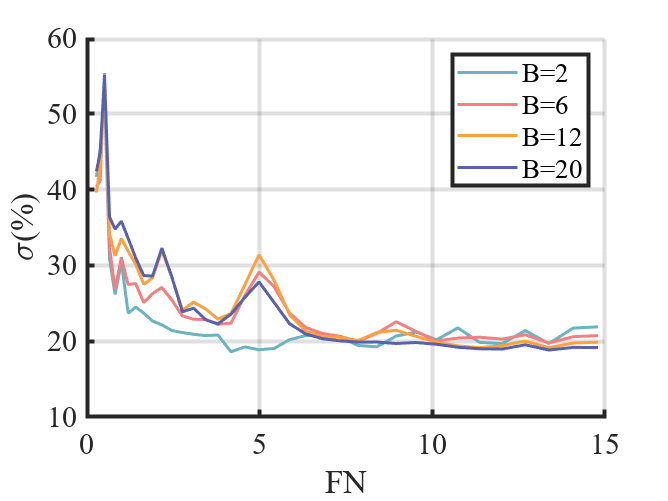

figure
hold on
colororder([color4;color3;color2;color1])
for ii=1:length(BB)
    plot(fn(ii,:),sigma(ii,:),'LineWidth',1.5)
end
set(gca,'LineWidth',2,'fontname','Times New Roman','Fontsize',15)
xlabel('FN')
ylabel('\sigma(%)')
grid on
legend(['B=' num2str(BB(1))],['B=' num2str(BB(2))], ...
    ['B=' num2str(BB(3))],['B=' num2str(BB(4))])